### Assumptions:

    1. Small angles: $\sin \left(\theta \;\right)=\theta \;$

clear all
k = [100,100,100,100];
c = [0,0,0,0];


syms m1 m2 m3 I1 % mass 1,2,3 & inertia for M1
syms k1 k2 k3 k4 % spring constants
syms c1 c2 c3 c4 % damping constants
syms L1 L2 %distance of point A & B to the centre of M1
 syms k0 % tortinal spring constant


syms x1 x1_dot x1_ddot % displacement, velocity & acceleration of M1
syms x2 x2_dot x2_ddot % displacement, velocity & acceleration of M2
syms x3 x3_dot x3_ddot % displacement, velocity & acceleration of M3

syms theta theta_dot theta_ddot % angluar displacement, velocity & acceleration of M1





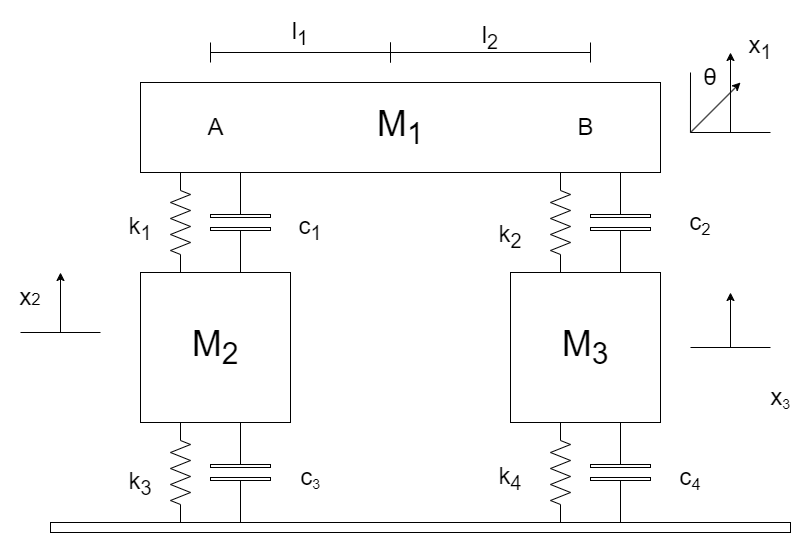

F_A = k1*(x1-x2-L1*theta)+c1*(x1_dot -x2_dot-L1*theta_dot) - k0 *(theta)/L1
F_B = k2*(x1-x3+L2*theta)+c2*(x1_dot -x3_dot+L2*theta_dot) + k0 *(theta)/L2

F2 =k3*(x2) + c3*(x2_dot)
F3 = k4*(x3) + c4*(x3_dot)

Create Equations based on these forces & newtons 2nd law

EQ_2 = m2*x2_ddot == F_A - F2
EQ_3 = m3*x3_ddot == F_B - F3


EQ_1 = m1 * x1_ddot == -(F_A + F_B)

Create the equation for the roll of the rig

EQ_1_Roll = I1 * theta_ddot == F_A*L1-F_B*L2




System_EQ = [EQ_1;
             EQ_1_Roll;
             EQ_2;
             EQ_3]
matrix_format = [x1_ddot, theta_ddot,x2_ddot,x3_ddot,...
                 x1_dot, theta_dot, x2_dot, x3_dot,...
                 x1,     theta,      x2,     x3;]

[A,F_Mat] = equationsToMatrix(System_EQ,matrix_format)
M_Mat = A(:,1:4)
C_Mat = A(:,5:8)
K_Mat = A(:,9:12)





### Creating Simulink Model for SImulated solution

% MODEL="Simulink_4DOF_Model"
% if(4==exist(MODEL))
%     close_system(MODEL,0);
%     delete(MODEL);
% end
% new_system(MODEL)
% open_system(MODEL)
%  matlabFunctionBlock( [MODEL+'/my_M_mat'], M_Mat);
%     matlabFunctionBlock( [MODEL+'/my_C_mat'], C_Mat);    
%     matlabFunctionBlock( [MODEL+'/my_K_mat'], K_Mat);   
%     matlabFunctionBlock( [MODEL+'/my_F_col'], F_Mat);
% 
% purple_str = '[0.6, 0.6, 1]';
%     set_param([MODEL+'/my_M_mat'],'BackgroundColor',purple_str,'Position', [-325   262  -190   478]);
%     set_param([MODEL+'/my_C_mat'],'BackgroundColor',purple_str,'Position', [45   -46   180   271]);    
%     set_param([MODEL+'/my_K_mat'],'BackgroundColor',purple_str,'Position', [45   308   180   617]);
%     set_param([MODEL+'/my_F_col'],'BackgroundColor',purple_str,'Position', [610     2   735   563]);    
% 
% 












### Modal Analysis

Start off by putting actual values into all the symbolic variables

sym_list = [ m1, m2, m3, I1,...
k1, k2, k3, k4,...
c1, c2, c3, c4,...
L1, L2, k0];
value_list = zeros(size(sym_list));

test = readtable("car_rig_data.xlsx")
for i=1:size(value_list,2)
    value_list(1,i) = test.Var2(i);
end

M_matrix_raw = double(subs(M_Mat,sym_list,value_list))
C_matrix_raw = double(subs(C_Mat,sym_list,value_list))
K_matrix_raw = double(subs(K_Mat,sym_list,value_list))


A = inv(M_matrix_raw)*K_matrix_raw;
[eigenVector, eigenValues] = eig(A);
[~,ind] = sort(diag(eigenValues));

eigenVector=eigenVector(:,ind);
eigenValues=eigenValues(:,ind);
wn=[4];
for i=1:size(eigenValues,1)
%    vec(:,i) = vec(:,i)/max(abs(eigenVector(:,i)));
   wn(i) = sqrt(abs(sort(eigenValues(i,i))));
    
end

Testing normalisation of data. I don't really see the use.


%% Testing Normalisation of Eigen Values, should result in the same value as
tmp         = eigenVector.' * M_matrix_raw * eigenVector;
tmp_row     =  diag(tmp)';
eVec_PHI    = eigenVector ./ sqrt( tmp_row );

Im_mat      = eVec_PHI.' * M_matrix_raw * eVec_PHI;
w2_mat      = eVec_PHI.' * K_matrix_raw * eVec_PHI;
w_list = sqrt( double(diag(w2_mat)) );
w_table = array2table( [abs(w_list), abs(w_list/(2*pi))], "VariableNames", {'w_radpersec', 'f_Hz'}  )

my_4dof_sym_list = [x1,  theta,    x2,  x3]
my_4dof_str_list = string(my_4dof_sym_list);


NUM_DOF             =   size(eVec_PHI,1);
MAX_NORM_eVec_PHI   = eVec_PHI ./ repmat(max(abs(eVec_PHI)), NUM_DOF, 1);

mode_table = array2table( MAX_NORM_eVec_PHI, ...
                          "VariableNames",  "MODE_"+[1:4], ...
                          "RowNames"     ,  my_4dof_str_list )



Pull in Experimental Data for comparison

experimental_data = Extract_Half_Car_Rig_Data();
experimental_data


Select Which Data Set you want


Selection = 5;
Lift_position_selection = 'Centre';
Suspension_selection = '1500';
Mass_selection = '0';
index=0;
largest_var=0;
for i=1:length(experimental_data)
    if strcmpi(experimental_data(i).Lift_Position,Lift_position_selection) &...
        strcmpi(experimental_data(i).damping,Suspension_selection) & ...
        strcmpi(experimental_data(i).mass,Mass_selection)
    
        Selected_data_set(i) = experimental_data(i);
        if length(experimental_data(i).rawdata) > largest_var % if multiple data sets prioritise one with more data points
            largest_var =length(experimental_data(i).rawdata);
            index = i;

        end
    end
end

Selected_data_set = Selected_data_set(index);



figure_exp =  figure("name","Experimental");
if Selection ~= 5
    plot(Selected_data_set.cdata.time,Selected_data_set.rawdof(:,Selection+1));
else
    plot(Selected_data_set.cdata.time,Selected_data_set.rawdof(:,2:5));
end
legend("M1\_Pos","M1\_Roll","M2\_Pos","M3\_Pos");
% ylim([-max(abs(Init_param)),max(abs(Init_param))]);
xlim([0,8]);


experimental_init_var = Selected_data_set.init_var;



Running Model

Edit Damping

use_init_var_from_experimental = true;

Damping_Slider = 520;
    M1_Pos = 0.04;
    M1_Roll =0;
    M2_Pos =0;
    M3_Pos =0;



value_list_2 = value_list;
value_list_2(9:10) = Damping_Slider;

M_matrix_subbed = double(subs(M_Mat,sym_list,value_list_2));
C_matrix_subbed = double(subs(C_Mat,sym_list,value_list_2));
K_matrix_subbed = double(subs(K_Mat,sym_list,value_list_2));


if use_init_var_from_experimental

    Init_param = experimental_init_var
else
    Init_param = [M1_Pos,M1_Roll,M2_Pos,M3_Pos];
    Init_param_dot = [0;0;0;0];
end

simOut = sim("x4DOF_Model");

test = simOut.yout{1}.extractTimetable;


figure("name","Simulation");
if Selection ~= 5
    plot(test.Time,test.Data(:,Selection));
else
    plot(test.Time,test.Data);
end
legend("M1\_Pos","M1\_Roll","M2\_Pos","M3\_Pos")
ylim([-max(abs(Init_param)),max(abs(Init_param))]);
xlim(seconds([0,10]));


